Dataset=imageDatastore('Fruit','IncludeSubfolders',true,'LabelSource','foldernames');
[Training_Dataset,Validation_Dataset,Testing_Dataset]=splitEachLabel(Dataset,0.7,0.15,0.15);
net=googlenet;
%analyzeNetwork(net);
Input_Layer_Size=net.Layers(1).InputSize(1:2);
Resized_Training_Image=augmentedImageDatastore(Input_Layer_Size,Training_Dataset);
Resized_Validation_Image=augmentedImageDatastore(Input_Layer_Size,Validation_Dataset);
Resized_Testing_Image=augmentedImageDatastore(Input_Layer_Size,Testing_Dataset);



Feature_Learner=net.Layers(142);
Output_Classifier=net.Layers(144);
Number_0f_Classes=numel(categories(Training_Dataset.Labels));
New_Feature_Learner=fullyConnectedLayer(Number_0f_Classes,...
    'Name','Fruit Feature Learner',...
    'WeightLearnRateFactor',10,...
    'BiasLearnRateFactor',10);
New_Classifier_Layer=classificationLayer('Name','Fruit Classifier');
Layer_Graph=layerGraph(net)

Layer_Graph =   LayerGraph with properties:

     InputNames: {'data'}
    OutputNames: {'output'}
         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]


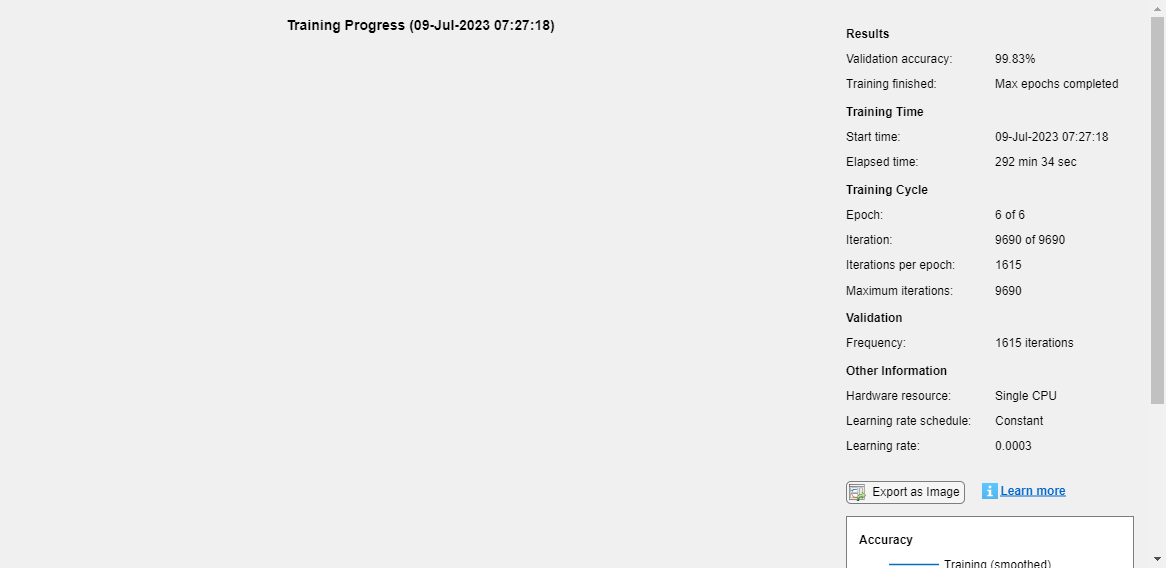

New_Layer_Graph=replaceLayer(Layer_Graph,Feature_Learner.Name,New_Feature_Learner);
New_Layer_Graph=replaceLayer(New_Layer_Graph,Output_Classifier.Name,New_Classifier_Layer);
%analyzeNetwork(New_Layer_Graph);
Size_of_Minibatch=5;
Validation_Frequency=floor(numel(Resized_Training_Image.Files)/Size_of_Minibatch);
Training_Options=trainingOptions('sgdm',...
    'MiniBatchSize',Size_of_Minibatch,...
    'MaxEpochs',6,...
    'InitialLearnRate',3e-4,...
    'Shuffle','every-epoch',...
    'ValidationData',Resized_Validation_Image,...
    'ValidationFrequency',Validation_Frequency,...
    'Verbose',false,...
    'Plots','training-progress');




net=trainNetwork(Resized_Training_Image,New_Layer_Graph,Training_Options);

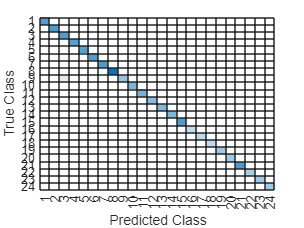


predictedLabels = classify(net, Resized_Testing_Image);
trueLabels = Testing_Dataset.Labels;

confusionMatrix = confusionmat(trueLabels, predictedLabels);

figure;
confusionchart(confusionMatrix);